# Pre-processing

%%initial image
tic
clear;
clc;
row=256;
colum=256;
img=imread('monkey.jpeg');
img=imresize(img,[row,colum]);
img=rgb2gray(img);
% img=histeq(img);
img=im2double(img);
origin=img;
% img=medfilt2(img);
toc

Elapsed time is 0.110827 seconds.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Scale-Space Extrema Detection

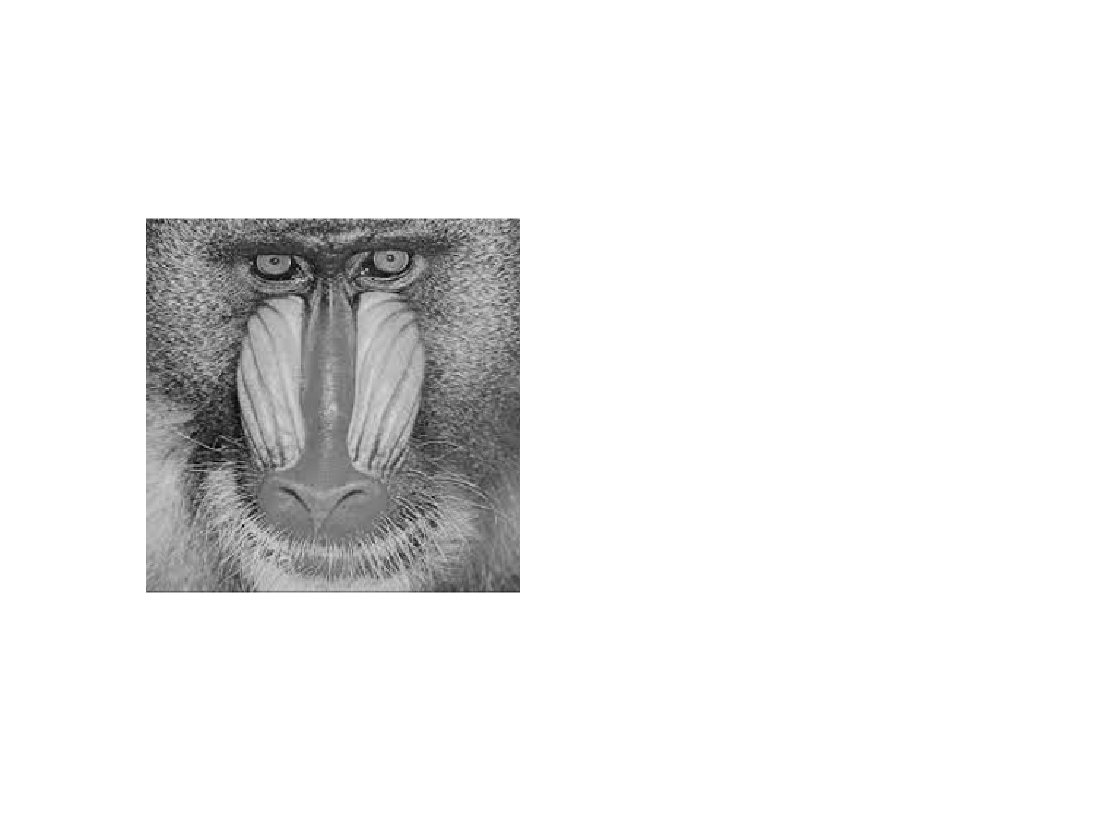

tic
% original sigma and the number of actave can be modified. the larger
% sigma0, the more quickly-smooth images
sigma0=sqrt(2);
octave=3; % number of octaves
level=3;  % number of scales levels within an octave 
D=cell(1,octave); % row of 3 cells for containng data relevant to the corresponding octaves
for i=1:octave 
D(i)=mat2cell(zeros(row*2^(2-i)+2,colum*2^(2-i)+2,level),row*2^(2-i)+2,colum*2^(2-i)+2,level); % each octave is represented by one of the 3 cells of D
% and each such cell contains the difference of the base gaussian of the
% octave given by a scale value of sqrt(2)^(octave number -1)*sigma_0 and the
% scale values of the different levels within the octave that are members
% of a GP with common ratio sqrt(2)^(number of levels in an octave) and
% initial value = base gaussian scale of the octaves
end
% first image in first octave is created by interpolating the original one.
% By interpolation, we mean that each pixel is replaced by 4 pixels of the same intensity 
temp_img=kron(img,ones(2)); % replace every 1 pixel by 4 pixels of the same intensity 
temp_img=padarray(temp_img,[1,1],'replicate'); % pad all sides by intensities that are the same as the border intensities kust beisde these padding pixels
% temp_img has dimensions (2*row+2,2*col+2)
figure(2)
subplot(1,2,1);
imshow(origin) % displaying the original image in the second sub-figure, this will be marked by the extracted key-points in subsequent steps 

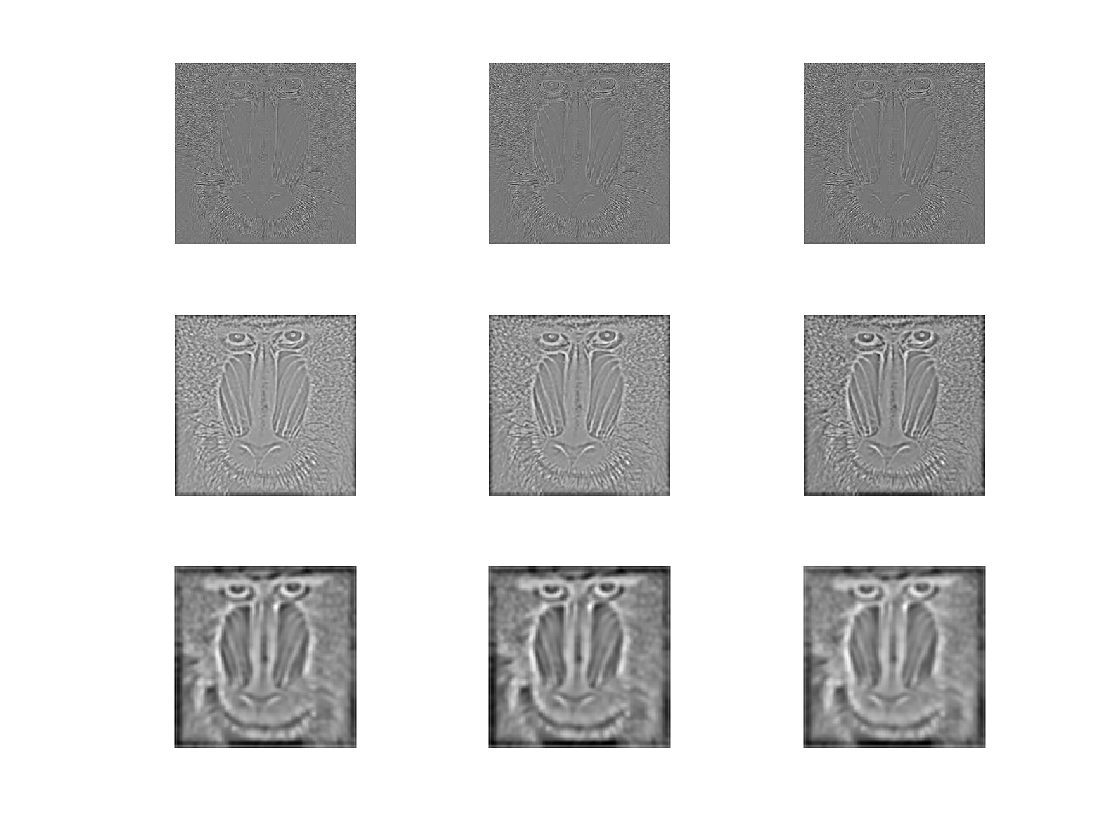

% filling all the levels of all the octaves of the Difference of Gaussian
% map in the following nested loop
for i=1:octave
    temp_D=D{i}; % make all updates to temp_D and then store the value in D(i)
    if(i==1)
        L1=temp_img;
    end
    for j=1:level
        scale=sigma0*sqrt(2)^((i-1)+(j/level));
        % this means that for the i^th octave, base scale = sigma0*2^(i-1),
        % first level in that octave is 2 times, second is 4 times etc of
        % this base scale the 3rd one in the octave is equal to the base
        % for the next octave (for the case, level=3)
        % the last level of an octave is retained as temp_img to serve as
        % the base scale of the next octave
        p=(level)*(i-1);
        figure(1);
        subplot(octave,level,p+j);
        f=fspecial('gaussian',[1,floor(6*scale)],scale);  % f is the gaussian filter that we will apply on the image, the size 
        % and standard deviation vaues for the filter have been mentioned     
        
        % IMPORTANT h = fspecial('gaussian',hsize,sigma) returns a rotationally symmetric Gaussian lowpass filter of size hsize with standard deviation sigma. Not recommended. Use imgaussfilt or imgaussfilt3 instead.
       
        % because the contribution of the pixels located more than 3 sigmas
        % from the central pixel have negligible contribution to the
        % blurred pixel being created 
        % we have however doubled distance on both sides for which the same
        % pixel intensity is present so 2*3 = 6 is used in place of 3 only
        
        L2=conv2(L1,f'*f,'same');
        temp_D(:,:,j)=L2-L1;
        if(j==level)
            L1=L2(2:end-1,2:end-1); % the final filtered image for an octave is retained for serving as the base scale filtered image for the next octave
            % we remove the padding here to be able to sample this image
            % differently for the next octave
        end
        imshow(uint8(255 * mat2gray(temp_D(:,:,j)))); % displaying the j^{th} level in the i^{th} octave
    end
    D{i}=temp_D;
    L1=L1(1:2:end,1:2:end); % redcing the sampling frequency for higher scale valued octaves 
    % as the paper suggests this does not lead to any change in efficiency but drastically reduces the computation time
    L1=padarray(L1,[1,1],'both','replicate'); % padding the image to facilitate convolution at boundary pixels
end

toc

Elapsed time is 0.742116 seconds.



% origin is basically the original image
% remaining to be addressed - why are 2 images not appearing in figure 2
% why have we doubled scope of each pixel in both directions

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Keypoint Localistaionis

each pixel in the Dog map is compared with the 8 pixels in its immediate neighbourhood for the same scale value, the same pixel and its 8 neighbouring pixels for the two neighbouring scales if it is a minima/maxima amongs the values it is compared to, it is recorded in the array named extrema by noting 4 values for each such point, namely the octave number, the level number, the position and whether it is a maxima(1), or a minima(-1)

tic
interval=level-1; % for the first and last levels, no possibility of taking a difference on one of the sides with neighbouring scales,
% so k varies from 2 to interval in subsequent loops
number=0; % number records the number of values that can possibly be extremas 
% it is intialised (through the following loop) to the number of pixels
% over all octaves and levels in the DoG map
for i=2:octave+1
    number=number+(2^(i-octave)*colum)*(2*row)*interval; % total number of sampled points in the DoG formulation
end
extrema=zeros(4,number); % 4 descriptors are being recorded for each extrema
% IMPORTANT can think of making this a 2d array
ext_num=1;
for i=1:octave
    [m,n,~]=size(D{i});
    m=m-2;  % removing 2 rows corresponding to the padding
    n=n-2;  % removing 2 columns corresponding to the padding
    positions=m*n/(4^(i-1)); % IMPORTANT dunno why downsizing by a double factor of 2 has been done here
    for k=2:interval      
        for j=1:positions
            x=ceil(j/n); % get the x -  horiontal position (column number) from the positions , IMPORTANT it should be j/m 
            % logic for the first octave - there are n multiples of m in
            % n*m which correspond to the n values x can tak each of which
            % is retained for m values for each n corresponding to the m
            % values of y per x
            y=mod(j-1,m)+1; % get the y -  vertical position (row number) from the positions
            compare=D{i}(x:x+2,y:y+2,k-1:k+1);
            % checking the value of the max and min over the matrix compare
            biggest=max(max(max(compare)));
            smallest=min(min(min(compare)));
            
            % if pixel and scale under consideration correspond to an extremum
            if(biggest==D{i}(x+1,y+1,k)) 
                % i for octave number, k for level number, j for volume position and 1 for maxima 
                extrema(1,ext_num)=i;
                extrema(2,ext_num)=k;
                extrema(3,ext_num)=j;
                extrema(4,ext_num)=1;
                ext_num=ext_num+1;
            else 
                if(smallest==D{i}(x+1,y+1,k))
                    % i for octave number, k for level number, j for volume position and 1 for maxima 
                    extrema(1,ext_num)=i;
                    extrema(2,ext_num)=k;
                    extrema(3,ext_num)=j;
                    extrema(4,ext_num)=-1;
                    ext_num=ext_num+1;
                end
            end     
        end % ending loop over j (octaves)
    end % ending loop over k (levels)
end % ending loop over i (octaves)

%IMPORTANT idx= extrema==0; % the positions in the initial extrema array that do not record any of the actual extremas
%IMPORTANT extrema(idx)=[];
extrema = extrema(:,1:ext_num-1); % retaining the positions in the extrema array that record the actual extremas
ext_num = ext_num-1;
toc

Elapsed time is 1.366201 seconds.


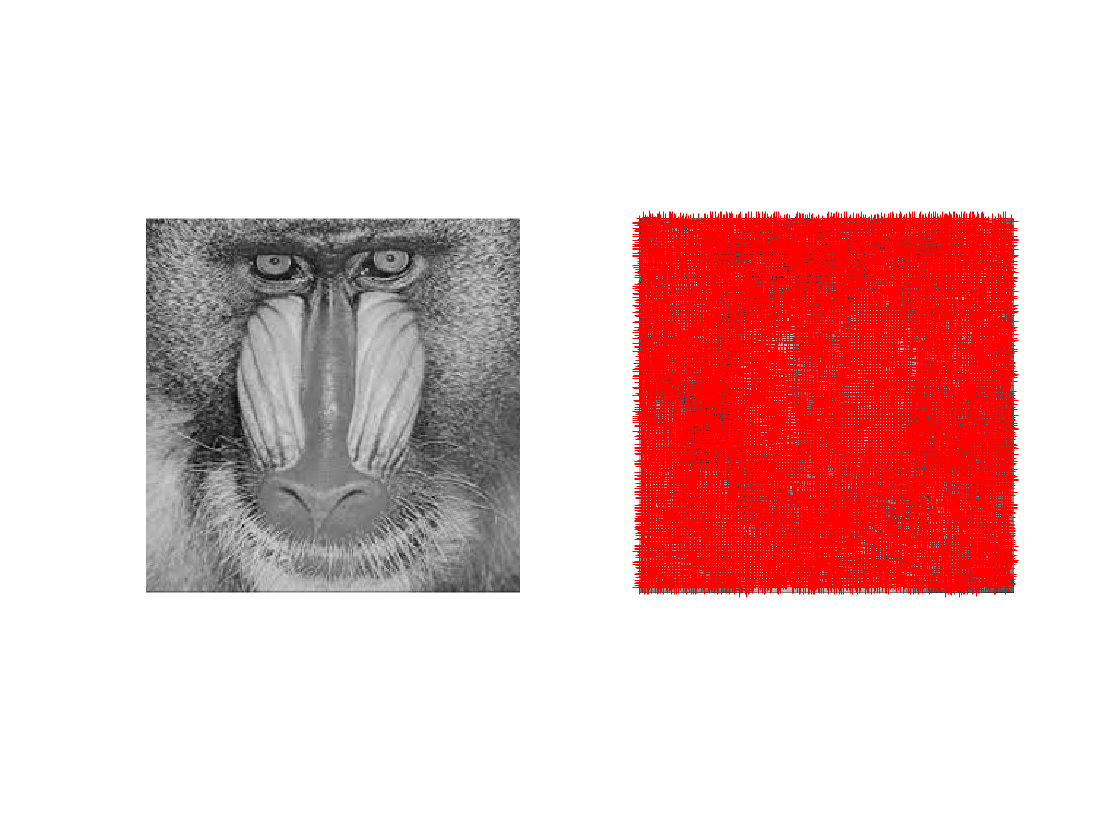


% transalting the observed extrema into pixel values actually present in the image
[m,n]=size(img);
x=floor((extrema(3,:)-1)./(n./(2.^(extrema(1,:)-2))))+1;
y=mod((extrema(3,:)-1),m./(2.^(extrema(1,:)-2)))+1;
ry=y./2.^(octave-1-extrema(1,:));
rx=x./2.^(octave-1-extrema(1,:));

% displaying the preliminary extrema caluculated in the first sub-figure of figure 2
figure(2)
subplot(1,2,2);
imshow(origin)
hold on
plot(ry,rx,'r+');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## accurate keypoint localization

%eliminate the point with low contrast or poorly localised on an edge
% x:|,y:-- x is for vertial and y is for horizontal

tic
% following value comes from the paper
threshold=0.1;
r=10;

[m,n]=size(img);

% generating second order derivative filters 
secondorder_x= [1,-2,1; 2,-4,2; 1,-2,1];
secondorder_y=[1,2,1; -2,-4,-2; 1,2,1]; % IMPORTANT can think of changing this to a better second derivative function

for i=1:octave
    for j=1:level
        test=D{i}(:,:,j);
        temp=-1./conv2(test,secondorder_y,'same').*conv2(test,[-1,-1;1,1],'same');
        D{i}(:,:,j)=temp.*conv2(test',[-1,-1;1,1],'same')*0.5+test;  %we are calculating double differentials of the filtered image
    end
end
ext_num

ext_num = 16288

size(extrema)

ans =            4       16288


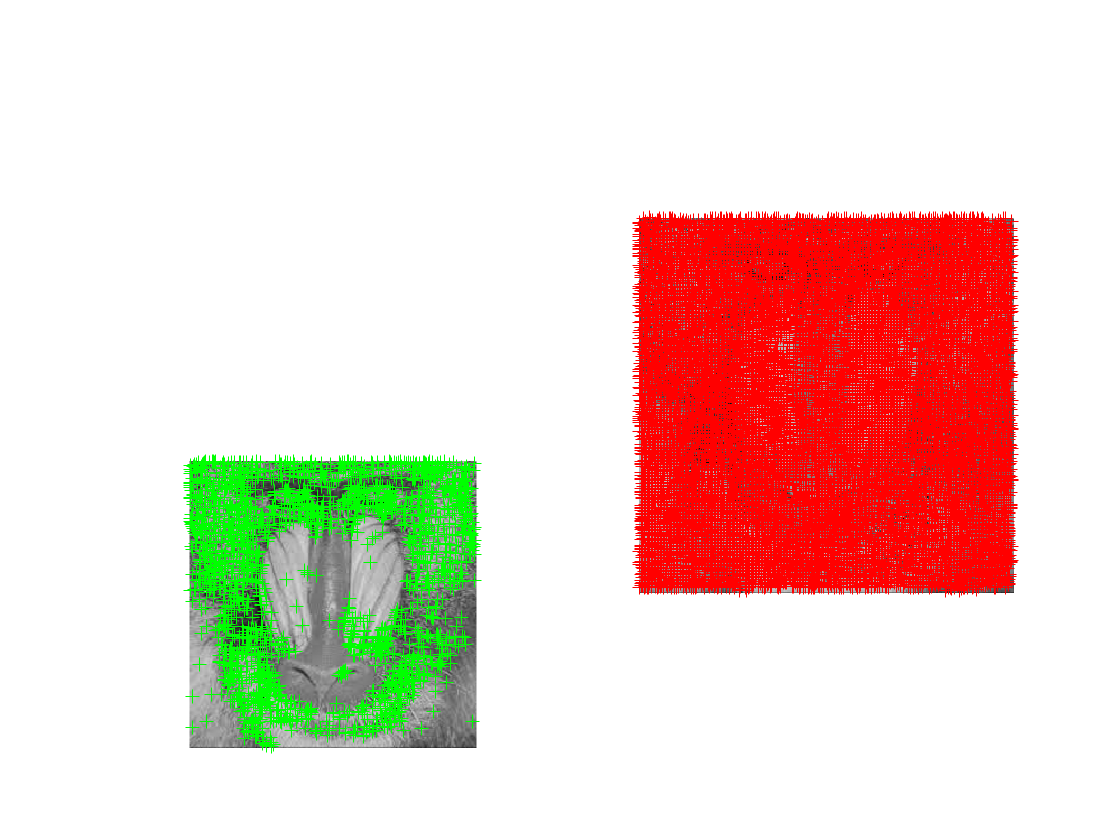

for i=1:ext_num
    %az = extrema(3,i)-1
    %bz = (n/(2^(extrema(1,i)-2)))
    x=floor((extrema(3,i)-1)/(n/(2^(extrema(1,i)-2))))+1;
    y=mod((extrema(3,i)-1),m/(2^(extrema(1,i)-2)))+1;
    rx=x+1;
    ry=y+1;
    rz=extrema(2,i);
    %i
    %extrema(1,i)
    z=D{extrema(1,i)}(rx,ry,rz);
    if(abs(z)<threshold)
        extrema(4,i)=0; % assigning 0 to the min/max deciding number for the extrema points with less contrast
    end
end
idx= 1-(extrema(4,:)==0);
extrema = extrema(:,(idx==1)); % removing the 4 features of each of the extrema points that have a 0 at the min/max value
ext_num=size(extrema,1);

% transalting the good contrast extrema into pixel values actually present in the image
x=floor((extrema(3,:)-1)./(n./(2.^(extrema(1,:)-2))))+1;
y=mod((extrema(3,:)-1),m./(2.^(extrema(1,:)-2)))+1;
ry=y./2.^(octave-1-extrema(1,:));
rx=x./2.^(octave-1-extrema(1,:));

% displaying the preliminary extrema caluculated in figure 2
figure(2)
subplot(2,2,3);
imshow(origin)
hold on
plot(ry,rx,'g+');

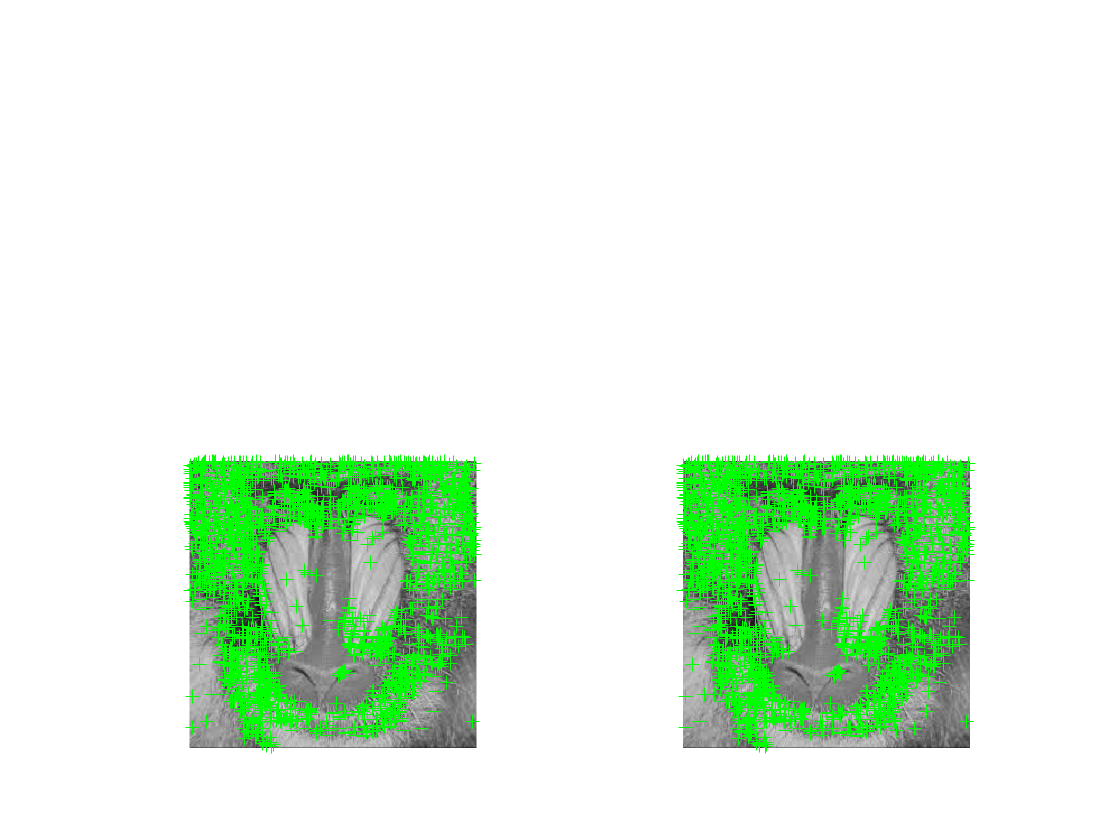


for i=1:ext_num
    x=floor((extrema(3,i)-1)/(n/(2^(extrema(1,i)-2))))+1;
    y=mod((extrema(3,i)-1),m/(2^(extrema(1,i)-2)))+1;
    rx=x+1;
    ry=y+1;
    rz=extrema(2,i);
        Dxx=D{extrema(1,i)}(rx-1,ry,rz)+D{extrema(1,i)}(rx+1,ry,rz)-2*D{extrema(1,i)}(rx,ry,rz);
        Dyy=D{extrema(1,i)}(rx,ry-1,rz)+D{extrema(1,i)}(rx,ry+1,rz)-2*D{extrema(1,i)}(rx,ry,rz);
        Dxy=D{extrema(1,i)}(rx-1,ry-1,rz)+D{extrema(1,i)}(rx+1,ry+1,rz)-D{extrema(1,i)}(rx-1,ry+1,rz)-D{extrema(1,i)}(rx+1,ry-1,rz);
        deter=Dxx*Dyy-Dxy*Dxy;
        R=(Dxx+Dyy)/deter;
        R_threshold=(r+1)^2/r;
        if(deter<0||R>R_threshold)
            extrema(4,i)=0;
        end
        
end
idx= 1-(extrema(4,:)==0);
extrema = extrema(:,(idx==1)); % removing the 4 features of each of the extrema points that have a 0 at the min/max value
ext_num=size(extrema,2 );

% transalting the good contrast extrema into pixel values actually present in the image
x=floor((extrema(3,:)-1)./(n./(2.^(extrema(1,:)-2))))+1;
y=mod((extrema(3,:)-1),m./(2.^(extrema(1,:)-2)))+1;
ry=y./2.^(octave-1-extrema(1,:));
rx=x./2.^(octave-1-extrema(1,:));

% displaying the preliminary extrema caluculated in figure 2
figure(2)
subplot(2,2,4);
imshow(origin)
hold on
plot(ry,rx,'g+');

toc

Elapsed time is 1.321285 seconds.




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Orientation Assignment(Multiple orientations assignment)

tic
kpori=zeros(ext_num,36); % key point orientations
numkpori=zeros(1,ext_num); % number of prominent orientations for each key point
f=1;
flag=1;
for i=1:ext_num
    %search in the certain scale
    scale=sigma0*sqrt(2)^(1/level)^((extrema(1,i)-1)*level+(extrema(2,i))); % scale value at which this key point gave an extrema
    width=2*round(3*1.5*scale); % a gaussian of this width decides the contribution of the neighbouring pixels
    % of this keypoint to its angle frequency histogram
    count=1;
    x=floor((extrema(3,i)-1)/(n/(2^(extrema(1,i)-2))))+1;
    y=mod((extrema(3,i)-1),m/(2^(extrema(1,i)-2)))+1;
    %make sure the point in the searchable area
    if(x>(width/2)&&y>(width/2)&&x<(m/2^(extrema(4*(i-1)+1)-2)-width/2-2)&&y<(n/2^(extrema(4*(i-1)+1)-2)-width/2-2))
        rx=x+1;
        ry=y+1;
        rz=extrema(4*(i-1)+2);
        reg_volume=width*width;%3? thereom
        % make weight matrix
        weight=fspecial('gaussian',width,1.5*scale);
        %calculate region pixels' magnitude and region orientation
        reg_mag=zeros(1,count);
        reg_theta=zeros(1,count);
    for xx=(rx-width/2):(rx+width/2-1)
        for yy=(ry-width/2):(ry+width/2-1)
            % m(x, y) = sqrt((L(x + 1, y) − L(x − 1, y))^2 + (L(x, y + 1) − L(x,y − 1))^2) 
            % -> magnitude of gradient
            reg_mag(count)=sqrt((D{extrema(1,i)}(xx+1,yy,rz)-D{extrema(1,i)}(xx-1,yy,rz))^2+(D{extrema(1,i)}(xx,yy+1,rz)-D{extrema(1,i)}(xx,yy-1,rz))^2); 
            % θ(x, y) = tan −1((L(x, y + 1) − L(x, y − 1))/(L(x + 1, y) − L(x − 1, y)))
            % -> direction of gradient
            reg_theta(count)=atan2((D{extrema(1,i)}(xx,yy+1,rz)-D{extrema(1,i)}(xx,yy-1,rz)),(D{extrema(1,i)}(xx+1,yy,rz)-D{extrema(1,i)}(xx-1,yy,rz)))*(180/pi);
            count=count+1;
        end
    end
    %make histogram 
    mag_counts=zeros(1,36); % number of bins 
    for x=0:10:359 % bin-width = 10, range of angles = 0 to 359 degrees
       mag_count=0;
       for j=1:reg_volume
           % for each of the points, adding a weighted value to the
           % frequency correpsonding to the bin in which its angle lies
           c1=-180+x;
           c2=-171+x;
           if(c1<0||c2<0)
           %making cases for comparing with arcta values that lie in -pi/2 to pi/2
           if(abs(reg_theta(j))<abs(c1)&&abs(reg_theta(j))>=abs(c2)) % for x > 180
               mag_count=mag_count+reg_mag(j)*weight(ceil(j/width),mod(j-1,width)+1);
           end
           else
               if(abs(reg_theta(j)>abs(c1)&&abs(reg_theta(j))<=abs(c2))) % for x <= 180
                   mag_count=mag_count+reg_mag(j)*weight(ceil(j/width),mod(j-1,width)+1);
               end
           end
       end
          mag_counts(x/10+1)=mag_count; % for every 10 width interval, store the frequency
    end
    % find the max histogram bar and the ones higher than 80% max
    [maxvm,~]=max(mag_counts);
     kori=find(mag_counts>=(0.8*maxvm)); % capturing the bin end points of the maximum frquency orientations
     kori=(kori*10+(kori-1)*10)./2-180; % finding their midpoints and converting from (0 to 360) to (-180,180) 
     %kpori(f:(f+length(kori)-1))=kori; % storing the max freq orientations for the keypoint being considered in this iteration 
     %f=f+length(kori); 
     numkpori(1,i)=length(kori);
     %temp_extrema=[extrema(1,i),extrema(2,i),extrema(3,i),extrema(4,i)];
     %temp_extrema=padarray(temp_extrema,[0,length(temp_extrema)*(length(kori)-1)],'post','circular');
     %long=length(temp_extrema);
     %minor(flag:flag+long-1)=temp_extrema;
     %flag=flag+long;
     kpori(i,1:length(kori))=kori;
    end
end
%%idx= minor==0;
%%minor(idx)=[];
%%extrema=minor; 
%%delete unsearchable points and add minor orientation points
%%idx= kpori==0;
%%kpori(idx)=[];
extrema = [extrema;numkpori];
ext_num=size(extrema,2);
toc

Elapsed time is 0.917002 seconds.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## keypoint descriptor

tic
d=4;% In David G. Lowe experiment,divide the area into 4*4. - IMP - can change this
pixel=4;% IMP - can change this
feature=zeros(d*d*8,ext_num);
for i=1:ext_num
    for jj=1:extrema(5,i)
        descriptor=zeros(1,d*d*8);% feature dimension is 128=4*4*8;
        width=d*pixel;
        %x,y centeral point and prepare for location rotation
        x=floor((extrema(3,i)-1)/(n/(2^(extrema(1,i)-2))))+1;
        y=mod((extrema(3,i)-1),m/(2^(extrema(1,i)-2)))+1;
        z=extrema(2,i);
            if((m/2^(extrema(1,i)-2)-pixel*d*sqrt(2)/2)>x&&x>(pixel*d/2*sqrt(2))&&(n/2^(extrema(1,i)-2)-pixel*d/2*sqrt(2))>y&&y>(pixel*d/2*sqrt(2)))
            sub_x=(x-d*pixel/2+1):(x+d*pixel/2);
            sub_y=(y-d*pixel/2+1):(y+d*pixel/2);
            sub=zeros(2,length(sub_x)*length(sub_y));
            j=1;
            for p=1:length(sub_x)
                for q=1:length(sub_y)
                    sub(:,j)=[sub_x(p)-x;sub_y(q)-y];
                    j=j+1;
                end
            end
            distort=[cos(pi*kpori(i,jj)/180),-sin(pi*kpori(i,jj)/180);sin(pi*kpori(i,jj)/180),cos(pi*kpori(i,jj)/180)];
        %accordinate after distort
            sub_dis=distort*sub;
            fix_sub=ceil(sub_dis);
            fix_sub=[fix_sub(1,:)+x;fix_sub(2,:)+y];
            patch=zeros(1,width*width);
            for p=1:length(fix_sub)
                patch(p)=D{extrema(1,i)}(fix_sub(1,p),fix_sub(2,p),z);
            end
            temp_D=(reshape(patch,[width,width]))';
            %create weight matrix.
            mag_sub=temp_D;        
            temp_D=padarray(temp_D,[1,1],'replicate','both');
            weight=fspecial('gaussian',width,width/1.5);
            mag_sub=weight.*mag_sub;
            theta_sub=atan((temp_D(2:end-1,3:1:end)-temp_D(2:end-1,1:1:end-2))./(temp_D(3:1:end,2:1:end-1)-temp_D(1:1:end-2,2:1:end-1)))*(180/pi);
            % create orientation histogram
            for area=1:d*d
            cover=pixel*pixel;
            ori=zeros(1,cover);
            magcounts=zeros(1,8);
            for angle=0:45:359
              magcount=0;
              for p=1:cover
                  x=(floor((p-1)/pixel)+1)+pixel*floor((area-1)/d);
                  y=mod(p-1,pixel)+1+pixel*(mod(area-1,d));
                  c1=-180+angle;
                  c2=-180+45+angle;
                  if(c1<0||c2<0)
                      if (abs(theta_sub(x,y))<abs(c1)&&abs(theta_sub(x,y))>=abs(c2))
                          
                          ori(p)=(c1+c2)/2;
                          magcount=magcount+mag_sub(x,y);
                      end
                  else
                      if(abs(theta_sub(x,y))>abs(c1)&&abs(theta_sub(x,y))<=abs(c2))
                          ori(p)=(c1+c2)/2;
                          magcount=magcount+mag_sub(x,y);
                      end
                  end              
              end
              magcounts(angle/45+1)=magcount;
            end
            descriptor((area-1)*8+1:area*8)=magcounts;
            end
            descriptor=normr(descriptor);
            % cap 0.2
            for j=1:numel(descriptor)
                if(abs(descriptor(j))>0.2)
                descriptor(j)=0.2;        
                end
            end
            descriptor=normr(descriptor);
            else
                continue;
            end
            feature(:,i)=descriptor';
    end
end
index=find(sum(feature));
feature=feature(:,index);
toc

Elapsed time is 1.428171 seconds.




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%